# Task#1

clc             
clear
StaticBreathing=readtable("Staticbreathing.csv");            %loading file

%Part (a)
disp("Part (a)");

Part (a)


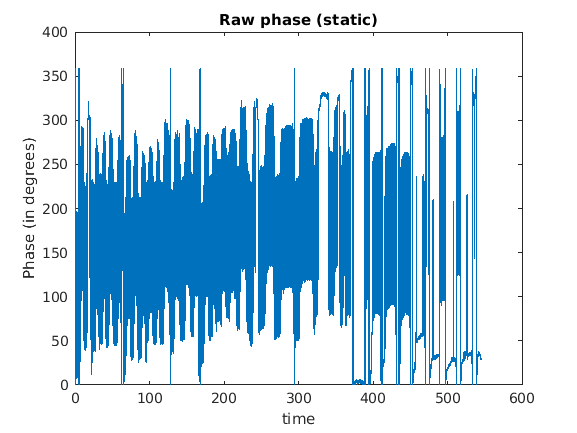

phase=StaticBreathing{:,"Var6"};    %extracting phase measurements from 6th coulmn of the static table
t=StaticBreathing{:,"Var8"};     %extracting time measurements from 8th coulmn of the static table

Ts = mean(diff(t));
fs = 1/Ts;                          %computing sampling frequency
%L=length(phase);
%time=(0:L-1)/fs;

for i=1:length(t)
    t(i)=i*(1/100);
end

plot(t,phase);                   %Plotting the Raw measurments
xlabel("time");
ylabel("Phase (in degrees)");
title("Raw phase (static)");


%Part (b)
disp("Part (b)")

Part (b)


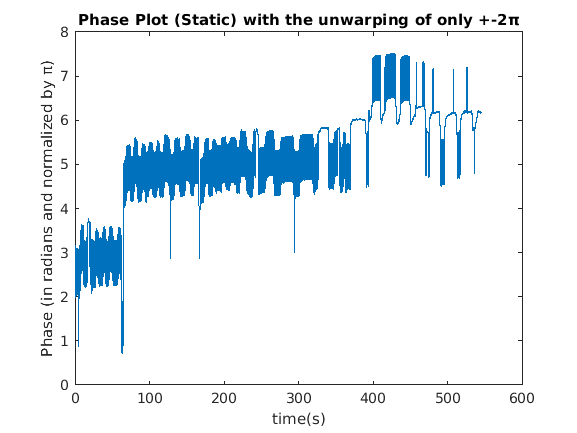

phase_proc1=phase;
for i=2:54507                       %A loop for going thorugh all the measurements to check for possible unwrap
    diff=phase_proc1(i)-phase_proc1(i-1);       %Calculating difference of two consecutive phases
    if(diff>=345 && diff<=375)                  %condition for unwraping of all phases close to +2π
        for n=i:54507
            phase_proc1(n)=phase_proc1(n)-360;
        end
    elseif(diff<=-345 && diff>=-375)             %condition for unwraping of all phases close to -2π
        for n=i:54507
            phase_proc1(n)=phase_proc1(n)+360;
        end
    else
        phase_proc1(i)=phase_proc1(i);
    end
    
end
phase_proc2=phase_proc1.*(1/180);     %converting phases from degrees to radians, normalized by π
plot(t,phase_proc2);             %Plotting phases with the unwraping of only +-2π
xlabel("time(s)");
ylabel("Phase (in radians and normalized by π)");
title("Phase Plot (Static) with the unwarping of only +-2π");


%Part (c)
disp("Part (c)");

Part (c)


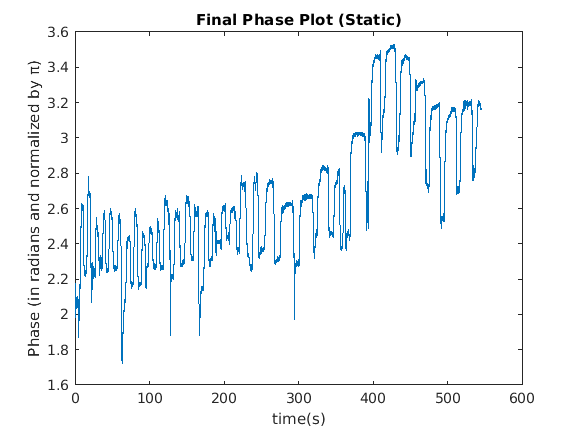

phase_proc=phase_proc1;
for i=2:54507       %A loop for going thorugh all the measurements to check for possible unwrap
    diff=phase_proc(i)-phase_proc(i-1);     %Calculating difference of two consecutive phases
    if(diff>=170 && diff<=190)              %condition for unwraping of all phases close to +π
        for n=i:54507
            phase_proc(n)=phase_proc(n)-180;
        end
    elseif(diff>=-190 && diff<=-170)
        for n=i:54507
            phase_proc(n)=phase_proc(n)+180;    %condition for unwraping of all phases close to -π
        end
        phase_proc(i)=phase_proc(i);
    end
end

%Part (d)

phase_processed=phase_proc.*(1/180);     %converting phases from degrees to radians, normalized by π
plot(t,phase_processed);
xlabel("time(s)");
ylabel("Phase (in radians and normalized by π)");
title("Final Phase Plot (Static)");

# Task#2

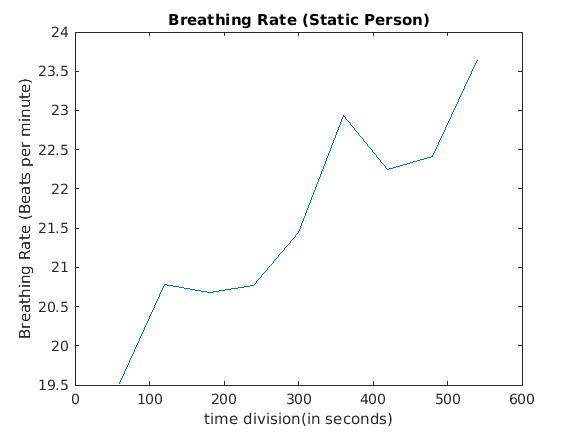


%peak1=findpeaks(phase_processed(1:6000));
pks1=findpeaks(phase_processed(1:6000));           %finding all the peaks in first 60 seconds
pks2=findpeaks(phase_processed(6001:12000));        %finding all the peaks in next 60 seconds
pks3=findpeaks(phase_processed(12001:18000));       % and so on
pks4=findpeaks(phase_processed(18001:24000));
pks5=findpeaks(phase_processed(24001:30000));
pks6=findpeaks(phase_processed(30001:36000));
pks7=findpeaks(phase_processed(36001:42000));
pks8=findpeaks(phase_processed(42001:48000));
pks9=findpeaks(phase_processed(48001:54000));

BrRate1=length(pks1)/60;            %dividing number of peaks by 60 to get breathing rate per minute
BrRate2=length(pks2)/60;
BrRate3=length(pks3)/60;
BrRate4=length(pks4)/60;
BrRate5=length(pks5)/60;
BrRate6=length(pks6)/60;
BrRate7=length(pks7)/60;
BrRate8=length(pks8)/60;
BrRate9=length(pks9)/60;

Breathing=[BrRate1 BrRate2 BrRate3 BrRate4 BrRate5 BrRate6 BrRate7 BrRate8 BrRate9];        %Breathing rate vector
time_scale=[60 120 180 240 300 360 420 480 540];            %Time scale
plot(time_scale,Breathing);     %plotting breathing rate(in breath per minutes) against time (in second)
title("Breathing Rate (Static Person)");
xlabel("time division(in seconds)");
ylabel("Breathing Rate (Beats per minute)");

# Task#3

NonStaticBreathing=readtable("NonStaticbreathing.csv");      %loading file
%Part (a)
disp("Part (a)");

Part (a)


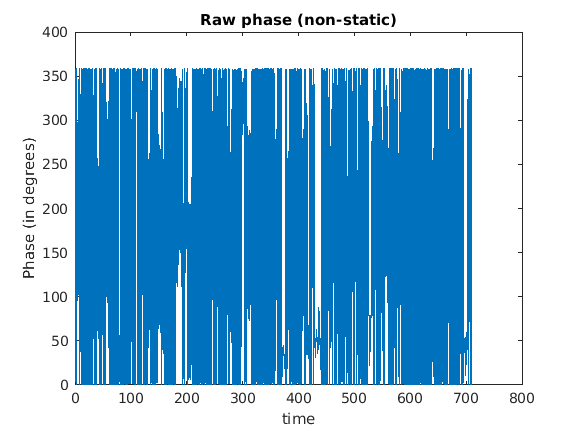

phaseNS=NonStaticBreathing{:,"Var6"};    %extracting phase measurements from 6th coulmn of the static table

for i=1:length(phaseNS)                  %    Time axis calculation
    time(i)=i*(1/100);
end

plot(time,phaseNS);                   %Plotting the Raw measurments
xlabel("time");
ylabel("Phase (in degrees)");
title("Raw phase (non-static)");


disp("Part (c)");

Part (c)


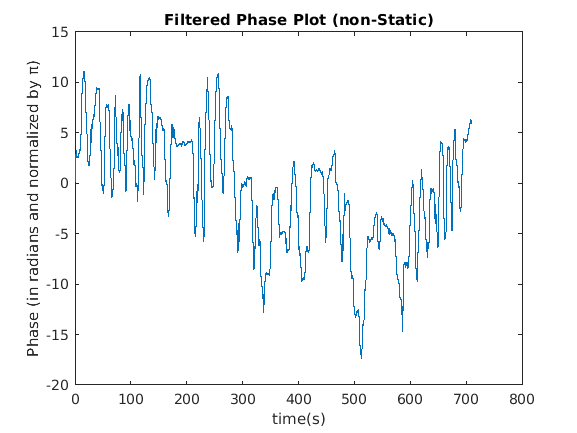

phase_procNS=phaseNS;
for i=2:length(phaseNS)       %A loop for going thorugh all the measurements to check for possible unwrap
    diff=phase_procNS(i)-phase_procNS(i-1);     %Calculating difference of two consecutive phases
    if(diff>=345 && diff<=375)                  %condition for unwraping of all phases close to +2π
        for n=i:length(phaseNS)
            phase_procNS(n)=phase_procNS(n)-360;
        end
    elseif(diff<=-345 && diff>=-375)             %condition for unwraping of all phases close to -2π
        for n=i:length(phaseNS)
            phase_procNS(n)=phase_procNS(n)+360;
        end
    elseif(diff>=170 && diff<=190)              %condition for unwraping of all phases close to +π
        for n=i:length(phaseNS)
            phase_procNS(n)=phase_procNS(n)-180;
        end
    elseif(diff>=-190 && diff<=-170)
        for n=i:length(phaseNS)
            phase_procNS(n)=phase_procNS(n)+180;    %condition for unwraping of all phases close to -π
        end
    else
        phase_procNS(i)=phase_procNS(i);
    end
end

phase_processedNS=phase_procNS.*(1/180);     %converting phases from degrees to radians, normalized by π
plot(time,phase_processedNS);
xlabel("time(s)");
ylabel("Phase (in radians and normalized by π)");
title("Filtered Phase Plot (non-Static)");

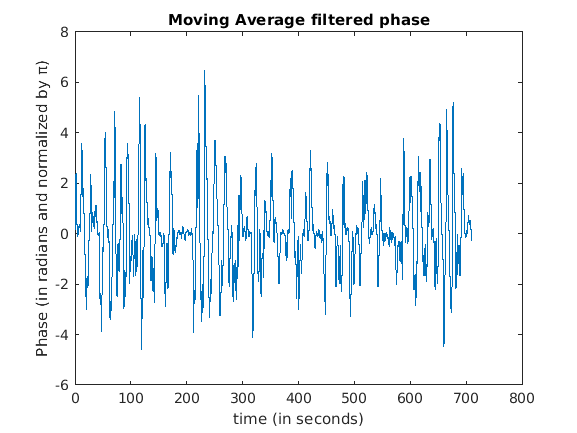



%Part (b)
M=300;               % I manually put M=300 cz I was getting best possible result 
                     % on it i.e., the small variation(due to chest movement)
                     % and large variations (due ot patient's movement) are
                     % being distinguished on the best on M=300
y = 1/M * movsum(phase_processedNS, [M-1 0]);  % Applying moving average filter
yplot=phase_processedNS-y;                     % Subtracting patient's movement(y) from total signal measured (phase_processedNS)
plot(time,yplot);                     %plotting chest movement aainst time
title("Moving Average filtered phase");
xlabel("time (in seconds)");
ylabel("Phase (in radians and normalized by π)");

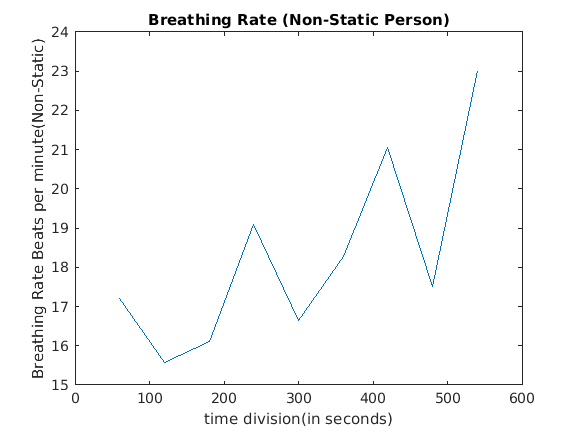


%Part (c)
pks1NS=findpeaks(yplot(1:6000));           %finding all the peaks in first 60 seconds
pks2NS=findpeaks(yplot(6001:12000));        %finding all the peaks in next 60 seconds
pks3NS=findpeaks(yplot(12001:18000));       % and so on
pks4NS=findpeaks(yplot(18001:24000));
pks5NS=findpeaks(yplot(24001:30000));
pks6NS=findpeaks(yplot(30001:36000));
pks7NS=findpeaks(yplot(36001:42000));
pks8NS=findpeaks(yplot(42001:48000));
pks9NS=findpeaks(yplot(48001:54000));

BrRate1NS=length(pks1NS)/60;            %dividing number of peaks by 60 to get breathing rate per minute
BrRate2NS=length(pks2NS)/60;
BrRate3NS=length(pks3NS)/60;
BrRate4NS=length(pks4NS)/60;
BrRate5NS=length(pks5NS)/60;
BrRate6NS=length(pks6NS)/60;
BrRate7NS=length(pks7NS)/60;
BrRate8NS=length(pks8NS)/60;
BrRate9NS=length(pks9NS)/60;

BreathingNS=[BrRate1NS BrRate2NS BrRate3NS BrRate4NS BrRate5NS BrRate6NS BrRate7NS BrRate8NS BrRate9NS];        %Breathing rate vector
time_scale=[60 120 180 240 300 360 420 480 540];            %Time scale
plot(time_scale,BreathingNS);     %plotting breathing rate(in breath per minutes) against time (in second)
title("Breathing Rate (Non-Static Person)");
xlabel("time division(in seconds)");
ylabel("Breathing Rate {Beats per minute(Non-Static)}");